% NBE-E4000 Principles of Biomedical Engineering
% Template for Problem 2 of Exercise 1
%
% The example uses thorax geometry models from ECGSIM software. The forward
% models were made using Helsinki BEM framework boundary element solvers.
% If you would like to use this kind of models for something please contact me!
%
% Matti Stenroos, matti.stenroos@aalto.fi

clear
close all
clc
% Put here the path of the folder, where you saved the plot functions that
% were given in the problem set.
%plotfunctionpath='~~/Documents/MATLAB/plotroutines/';
%addpath(plotfunctionpath);

% put here the full path to the attached model file
modelfile='~/Documents/MATLAB/e1_files/e1_ecgmodel';
load(modelfile,'m','thorax', 'myocardium', 'pericardium', 'L_peri','L_myo');
% thorax:   triangle mesh for the thorax boundary (see problem 1)
% pericardium: smooth triangle mesh for the outer boundary of the heart
% myocardium: triangle mesh for the boundaries of the heart muscle
% L_epi:    forward model from the nodes of epicardial mesh to the nodes of thorax
% L_myo:    forward model from the nodes of myocardial mesh to the nodes of thorax
% m:        "measured" EEG, 1 time sample, on the whole thorax

## This "%%" is a "block separator". Press ctrl-enter to run the code in blocks.

First, show how the model looks like

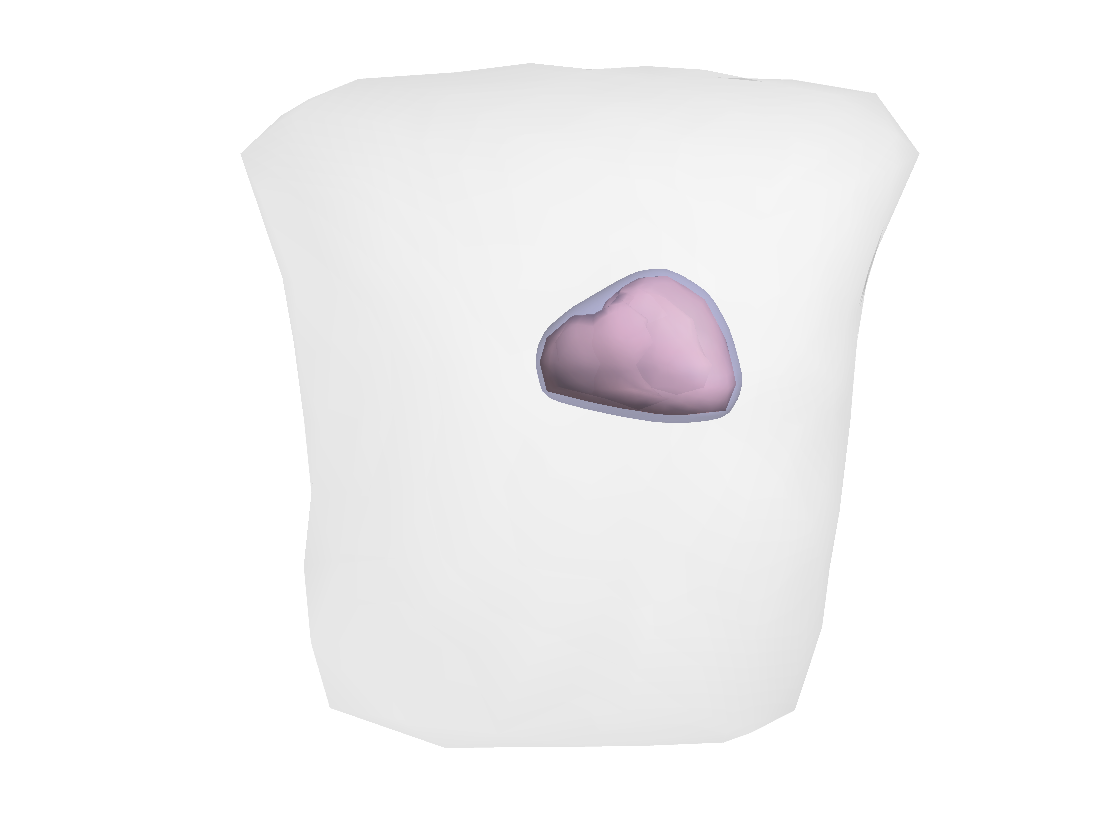

figure(1);clf;hold on;
PlotMesh(myocardium,'facecolor',[1 .7 .7],'facealpha',.8);
PlotMesh(pericardium,'facecolor',[.7 .7 1],'facealpha',.4);
PlotMesh(thorax,'facecolor',[.8 .8 .8],'facealpha',.1);

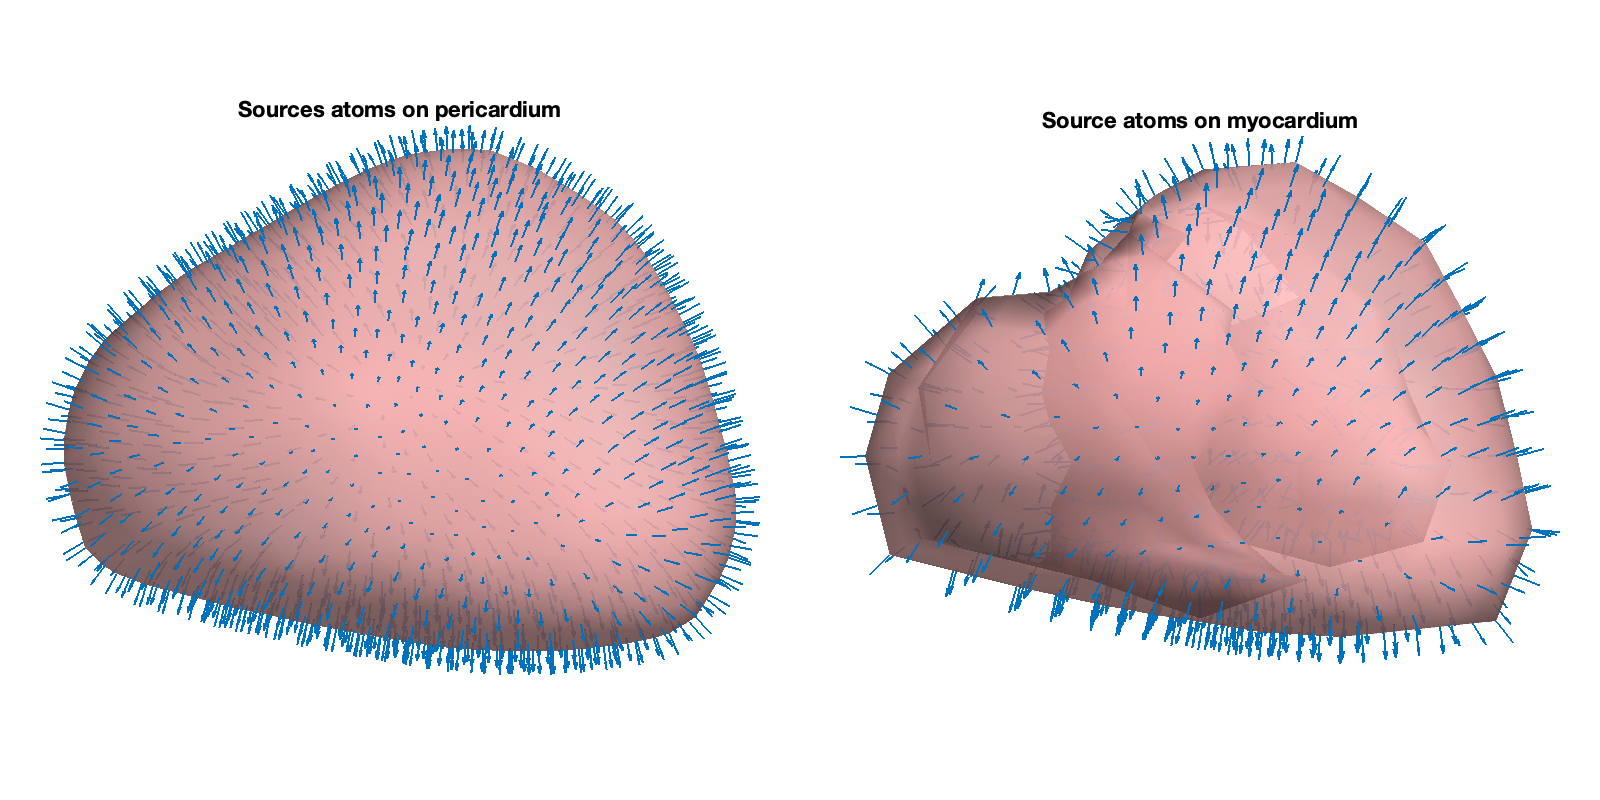

% Show, where and how are the source atoms of L_peri and L_myo
pw=400;ph=400;
set(figure(2),'position',[0 100 2*pw ph]);clf;
CreateAxes(1,2,1);hold on
PlotMesh(pericardium,'facealpha',.7);
PlotDipoles(pericardium.p,pericardium.nn,1);
title('Sources atoms on pericardium');
CreateAxes(1,2,2);hold on
PlotMesh(myocardium,'facealpha',.7);
PlotDipoles(myocardium.p,myocardium.nn,1);
title('Source atoms on myocardium');

## Then, show the data

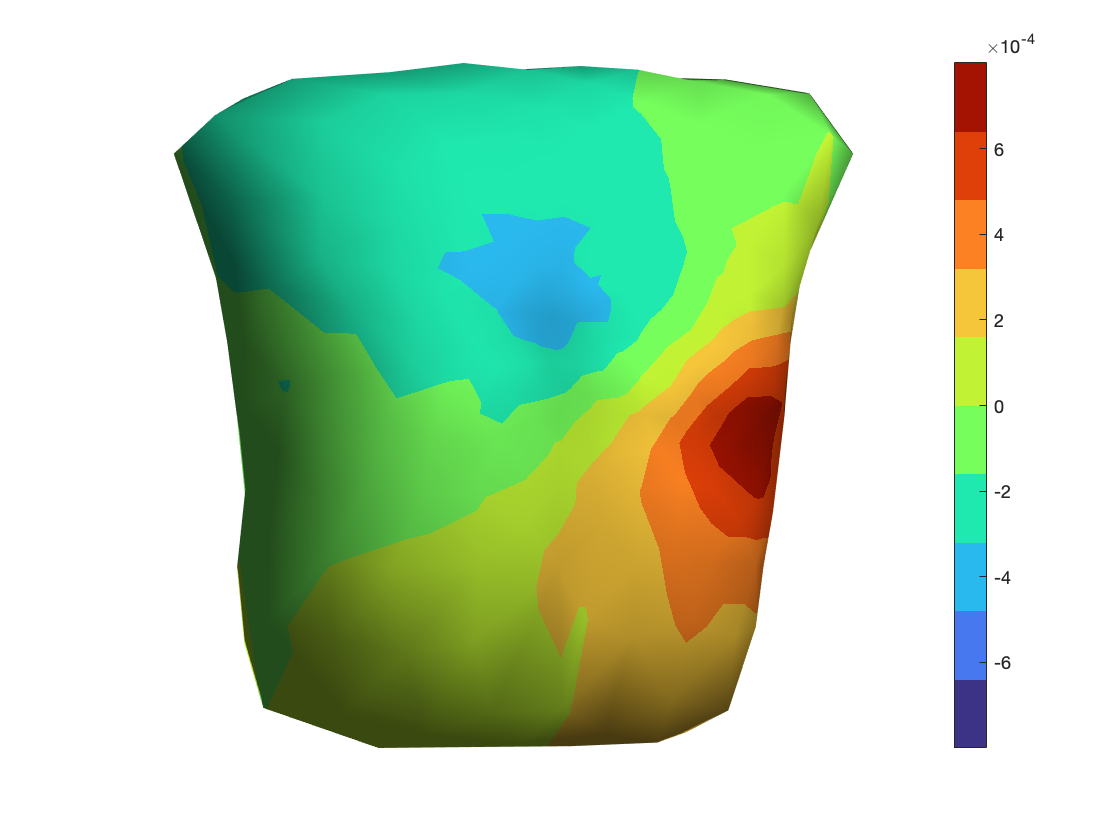

figure(3);clf;
PlotDataOnMesh(thorax,m); % plot anything on the mesh

## Build the source estimator for both given models: pericardium and myocardium.

This exersice is done in a colaboration with Hennah Terborg and Jan Andrys

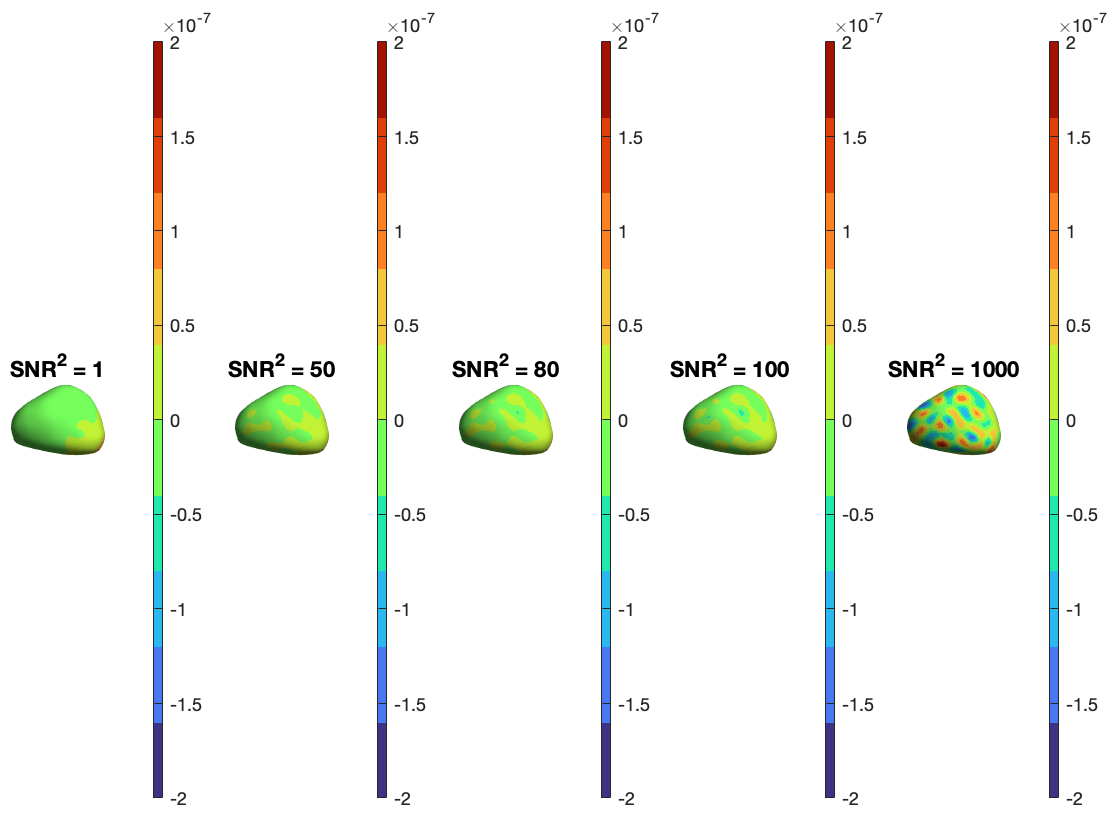

     1

    50

    80

   100

        1000



% For both models Tikhonov regularization is used
N_sensors = size(thorax.p,1);

% Pericardium calculations for different SNR
snr_peri_values = [1 50 80 100 1000];
figure(4);clf;
for i=1:length(snr_peri_values)
    snr = snr_peri_values(i);
    disp(snr);
    lambda2_peri = trace(L_peri*L_peri') / (N_sensors * snr);
    Linv_peri = L_peri'*pinv((L_peri*L_peri' + lambda2_peri*eye(N_sensors)));
    
    % calculate source estimations for pericardium model
    s_est_peri=Linv_peri*m;
    
    % plotting of 
    CreateAxes(1, length(snr_peri_values), i);
    PlotDataOnMesh(pericardium, s_est_peri, 'caxis', 2e-7);
    snr_title = sprintf("SNR^2 = %d", snr);
    title(snr_title);
end

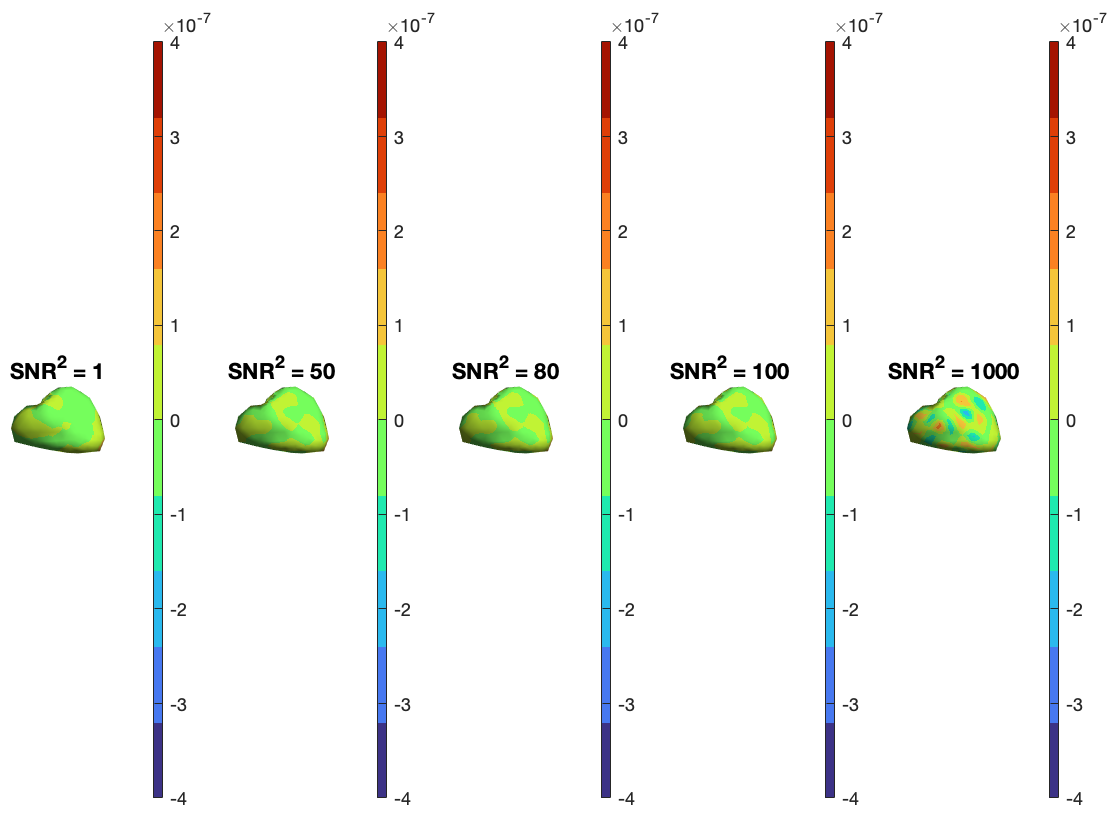

     1



Linv_myo = 	1.0e+-4 *

   -0.0147   -0.0093   -0.0168   -0.0168   -0.0065    0.0006   -0.0137   -0.0013    0.0015   -0.0105   -0.0111   -0.0009    0.0026   -0.0128    0.0003    0.0041    0.0312   -0.0187   -0.0018    0.0073    0.0081    0.0068    0.0062    0.1711   -0.0454    0.0180   -0.0055    0.0040    0.0069    0.0067    0.0928   -0.0317    0.0055   -0.0051   -0.0026    0.0044    0.0066    0.0082   -0.0229   -0.0062   -0.0005   -0.0015    0.0042    0.0072   -0.0092   -0.0163   -0.0124   -0.0016    0.0033    0.0058
    0.0008    0.0037    0.0003   -0.0017   -0.0032   -0.0023   -0.0009   -0.0023   -0.0019    0.0015    0.0027   -0.0004   -0.0011    0.0046    0.0066    0.0002   -0.0035   -0.0199    0.0094    0.0183    0.0065    0.0019    0.0000   -0.0176   -0.0357    0.1831    0.0085    0.0094    0.0022   -0.0004   -0.0054   -0.0348   -0.0206    0.0096    0.0021    0.0009    0.0003    0.0049    0.0076    0.0097   -0.0037   -0.0026   -0.0007   -0.0005    0.0047    0.0047    0.0022   -0.

    50



Linv_myo = 	1.0e+-3 *

   -0.0058   -0.0128   -0.0048    0.0026    0.0039    0.0008    0.0034    0.0018    0.0006   -0.0035    0.0066    0.0016    0.0004    0.0082   -0.0005   -0.0002   -0.0152   -0.0066   -0.0022   -0.0046   -0.0008    0.0003    0.0000    0.2003   -0.0753   -0.0149   -0.0037    0.0037    0.0022   -0.0002    0.0808   -0.0658   -0.0037    0.0021    0.0012    0.0027    0.0009   -0.0339   -0.0133    0.0063   -0.0010    0.0016    0.0013   -0.0006   -0.0186   -0.0034    0.0134   -0.0047   -0.0020   -0.0007
   -0.0025   -0.0002   -0.0019   -0.0010   -0.0003    0.0003   -0.0016    0.0009    0.0009   -0.0040   -0.0021    0.0037    0.0020   -0.0051    0.0036    0.0037    0.0011    0.0237    0.0082   -0.0178    0.0047    0.0040    0.0025    0.0279   -0.1033    0.0032   -0.0139    0.0031    0.0038    0.0012    0.0022    0.0290    0.0305   -0.0069    0.0038    0.0025    0.0015   -0.0055   -0.0082   -0.0036    0.0028   -0.0015    0.0003    0.0004   -0.0019   -0.0011    0.0027   -0.

    80



Linv_myo =    -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0003   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001   -0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.00

   100



Linv_myo =    -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0003   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001   -0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.00

        1000



Linv_myo =     0.0000    0.0000    0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0011    0.0000    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003    0.0002   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0001    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0001   -0.0000   -0.0001   -0.0002   -0.0002    0.0002   -0.0000   -0.0000    0.0000   -0.0001   -0.0003   -0.0005   -0.0001   -0.0000    0.0000    0.0000   -0.0001   -0.0000   -0.0001    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.00

% Myocardium calculations for different SNR
snr_myo_values = [1 50 80 100 1000];
figure(5);clf;
for i=1:length(snr_myo_values)
    snr = snr_myo_values(i);
    disp(snr);
    lambda2_myo = trace(L_myo*L_myo') / (N_sensors * snr);
    Linv_myo = L_myo'*pinv((L_myo*L_myo' + lambda2_myo*eye(N_sensors)))
    
    % calculate source estimations for pericardium model
    s_est_myo=Linv_myo*m;
    
    % plotting of 
    CreateAxes(1, length(snr_myo_values), i);
    PlotDataOnMesh(myocardium, s_est_myo, 'caxis', 4e-7);
    snr_title = sprintf("SNR^2 = %d", snr);
    title(snr_title);
end

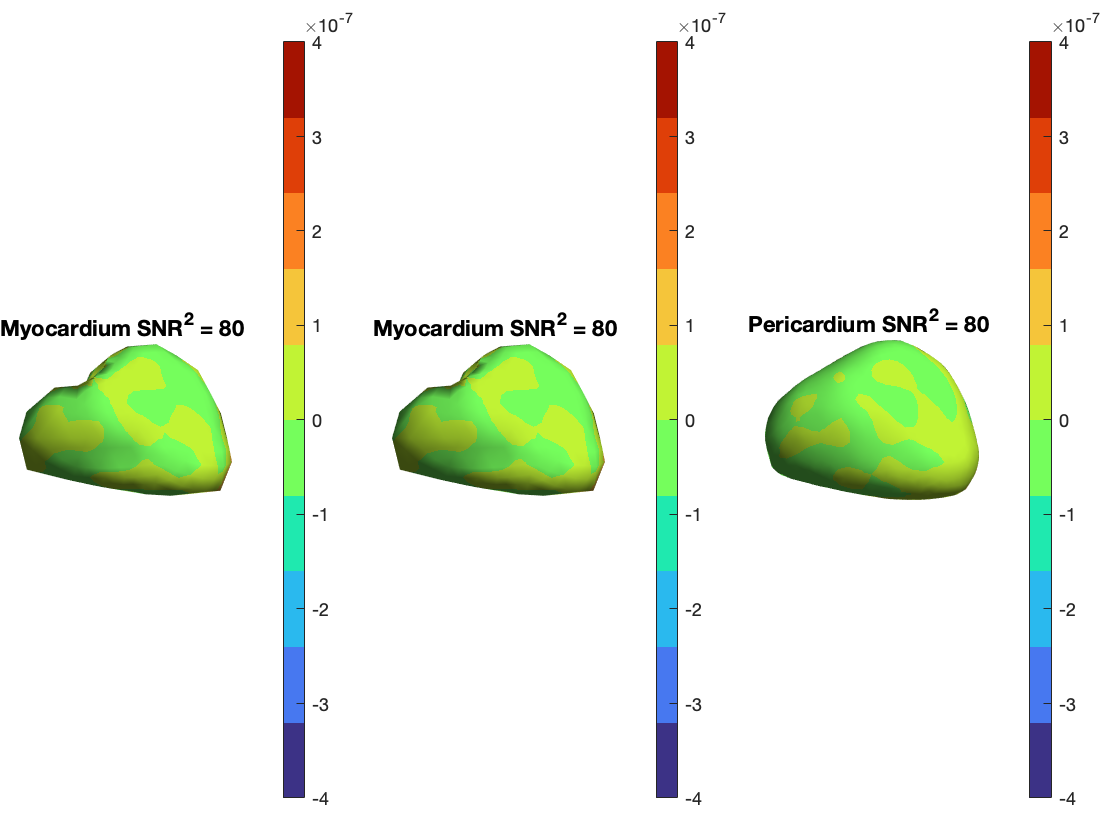

% Comparison of myocardium and pericardium models plotted on the thorax
figure(6);clf;

% choosing one SNR^2 for comparing
snr_final = 80;
lambda2_myo = trace(L_myo*L_myo') / (N_sensors * snr_final);
Linv_myo_final = L_myo'*pinv((L_myo*L_myo' + lambda2_myo*eye(N_sensors)));
s_est_myo_final=Linv_myo_final*m;
CreateAxes(1, 3, 1);
PlotDataOnMesh(myocardium, s_est_myo_final, 'caxis', 4e-7);
title_myo = sprintf('Myocardium SNR^2 = %d ', snr_final);
title(title_myo);
CreateAxes(1, 3, 2);
PlotDataOnMesh(myocardium, s_est_myo_final, 'caxis', 4e-7);
title(title_myo);

lambda2_peri = trace(L_peri*L_peri') / (N_sensors * snr_final);
Linv_peri_final = L_peri'*pinv((L_peri*L_peri' + lambda2_peri*eye(N_sensors)));
s_est_peri_final=Linv_peri_final*m;
CreateAxes(1, 3, 3);
PlotDataOnMesh(pericardium, s_est_peri_final, 'caxis', 4e-7);
title_peri = sprintf('Pericardium SNR^2 = %d ', snr_final);
title(title_peri);

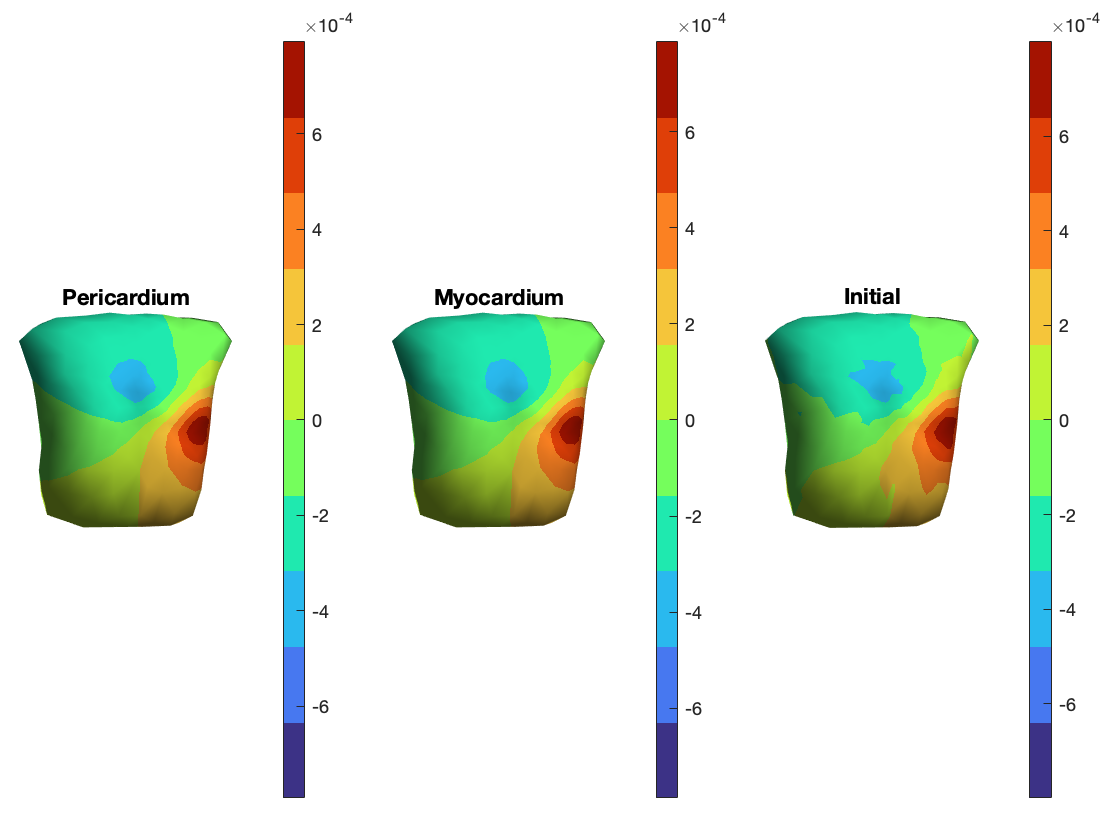


figure(7);clf;
CreateAxes(1, 3, 1);
m_peri = L_peri * s_est_peri_final;
PlotDataOnMesh(thorax, m_peri);
title("Pericardium");

CreateAxes(1, 3, 2);
m_myo = L_myo * s_est_myo_final;
PlotDataOnMesh(thorax, m_myo);
title("Myocardium");
CreateAxes(1, 3, 3);
PlotDataOnMesh(thorax, m);
title("Initial");

% error estimation
norm_myo = norm(m_myo - m, 2);
norm_peri = norm(m_peri - m, 2);

% high freq of the noise on high freq, still have source but 
% Task 4: snr to remove ill-conditioned
% reg method to render a unique solution